## **Digital Communication Systems Laboratory**

## **Laboratory 06**

### **Section 01**

The initial parameters are usually defined at the beginning of the program.

%TUID 915614617
clc; clear;
A = 1;              % Signal amplitude
rb = 2000;          % Fundamental frequency of signal
Tb = 1 / rb;        % Period of signal
fc = (6+20) * rb;
Tc = 1 / fc;
fs = 100 * fc;     % Sampling frequency
Ts = 1 / fs;        % Sampling period

### Section 02

#### **Modulation**

In the baseband:

    
$$s_{\textrm{base}} \left(t\right)=A\;\sin \left(\;2\pi \;f\;t+\theta \;\right)$$


    If the message is embedded in the amplitude A, the encoding is called Amplitude Shift Keying (ASK).

    If the message is embedded in the frequency *f*, the encoding is called Frequency Shift Keying (FSK).

    If the message is embedded in the phase $\theta$, the encoding is called Phase Shift Keying (PSK).

In the passband, the wave spectrum is transfered from the origin to a higher frequency, called as frequency of carrier or fc.

    
$$s_{\textrm{pass}} \left(t\right)=s_{\textrm{base}} \left(t\right)\cos \left(2\pi \;f_c \;t\right)=A\;\sin \left(2\pi \;r_b \;t+\theta \;\right)\;\cos \left(2\pi \;f_c \;t\right)$$


### Section 03

#### Phase Shift Keying (ASK)

Suppose there are 4 symbols in the symbol set. Therefore, at least 4 bits are needed to encode the symbols in binary format.

M = 16;                  % Number of symbols
Nb = ceil(log2(M));     % Number of bits per symbol

In PSK encoding, the phase will carry the information. So, the phase of the sinosoid will be changed by the symbols.

For example:


$$\begin{array}{l}
\textrm{Symbol}\;1:\theta =0\\
\textrm{Symbol}\;2:\theta =\frac{1}{16}\left(2\pi \right)\\
\textrm{Symbol}\;3:\theta =\frac{2}{16}\left(2\pi \right)\\
\textrm{Symbol}\;4:\theta =\frac{3}{16}\left(2\pi \right)\\
\ldotp \ldotp \ldotp \\
\textrm{Symbol}\;16:\theta =\frac{15}{16}\left(2\pi \right)=2\pi 
\end{array}$$


This symbol sets can be shown in the original indices and the PSK encoded format:

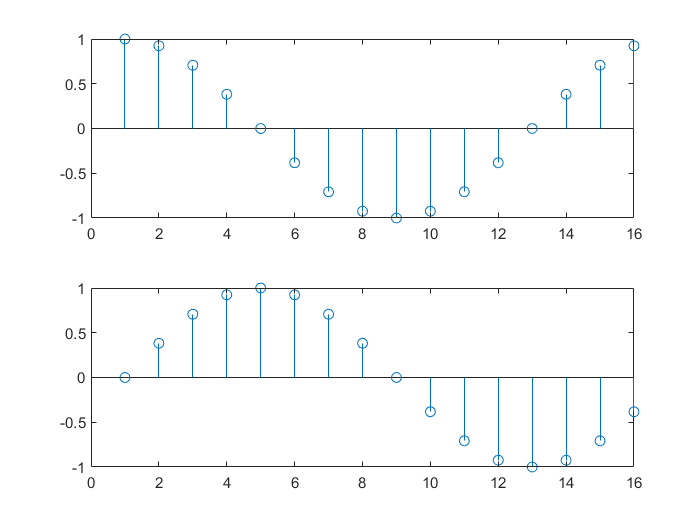

symbol_set = 1:M;                           % symbols' indices
TUID6=4;
%symbol_phase=[pi+5*TUID6,((pi/2)+5*TUID6),(pi+5*TUID6),(3*pi+5*TUID6)] %symbol phases using my TUID
%symbol_phase = [pi/4, 3*pi/4, 5*pi/4, 7*pi/4];  % symbols' phase
symbol_phase = (symbol_set-1)./M * 2 * pi;  % symbols' phase
figure(); 
subplot(2, 1, 1); stem(cos(symbol_phase));
subplot(2, 1, 2); stem(sin(symbol_phase));

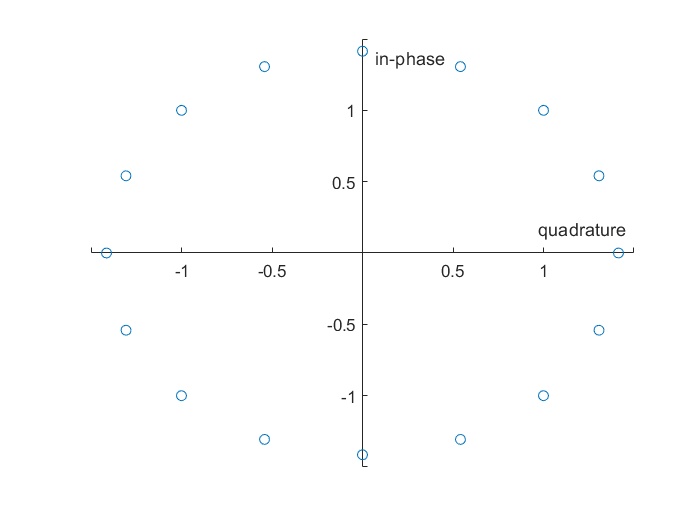

figure(); scatter(cos(symbol_phase)*sqrt(2), sin(symbol_phase)*sqrt(2))
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin')
xlabel('quadrature'); ylabel('in-phase');

The signal space can be shown in complex baseband format with the ConstellationDiagram class:

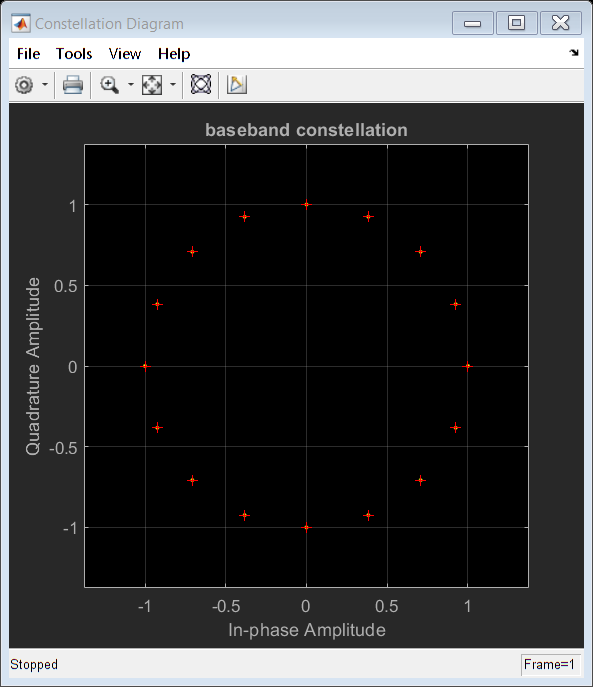

symbol_set_complex = exp(1j*symbol_phase);
constdiag = comm.ConstellationDiagram;
constdiag.Title = "baseband constellation";
% constdiag.SymbolsToDisplay = 10000;
constdiag.ShowLegend = false;
constdiag.ReferenceConstellation = symbol_set_complex';
constdiag(symbol_set_complex');
constdiag.release();

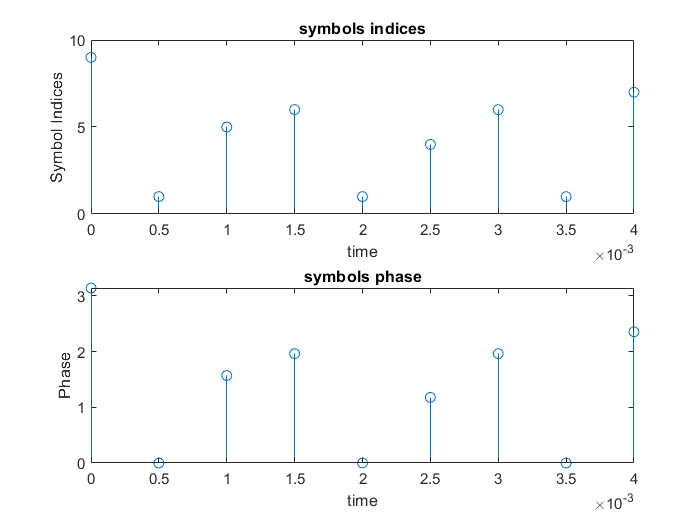

%msg = 1:M;                                  % message: a set of symbols
msg=[9 1 5 6 1 4 6 1 7];
msg_phase = symbol_phase(symbol_set(msg));  % mepping the symbol to the phase
t = (0:length(msg)-1)*Tb;
figure()
subplot(2, 1, 1); stem(t, msg); xlabel('time'); ylabel('Symbol Indices'); title('symbols indices');
subplot(2, 1, 2); stem(t, msg_phase); xlabel('time'); ylabel('Phase'); title('symbols phase');

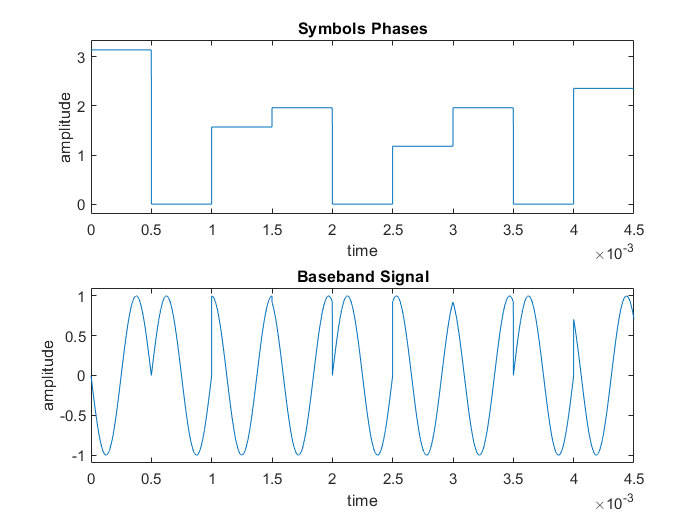

phases = rate_transition(msg_phase, rb, fs);
t = (0:length(phases)-1)*Ts;
signal = A * sin(2 * pi * rb * t + phases);
figure()
subplot(2, 1, 1); plot(t, phases); xlabel('time'); ylabel('amplitude'); ylim([min(phases)-0.2, max(phases)+0.2]); title('Symbols Phases')
subplot(2, 1, 2); plot(t, signal); xlabel('time'); ylabel('amplitude'); ylim([-A-0.1, +A+0.1]); title('Baseband Signal');

The baseband signal is modulated with carrier signal and the spectrum will shift in frequency domain from around the origin to the $f_c$ Hertz.

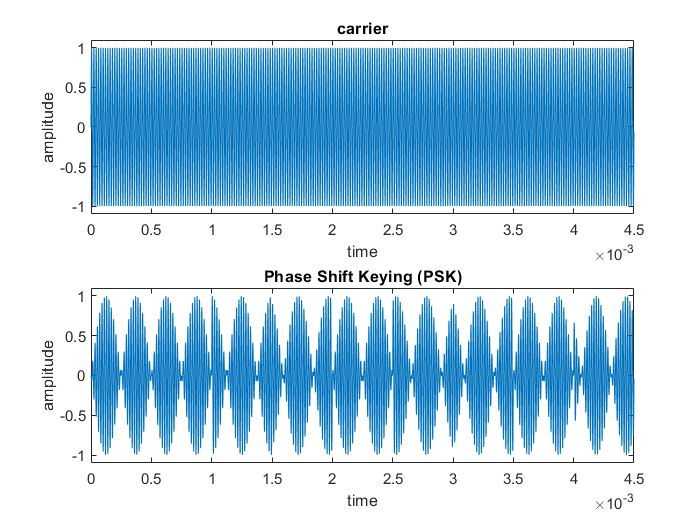

carrier = 1 * sin(2 * pi * fc * t + 0);
modulated = signal .* carrier;
figure()
subplot(2, 1, 1); plot(t, carrier); xlabel('time'); ylabel('amplitude'); ylim([-A-0.1, +A+0.1]); title('carrier');
subplot(2, 1, 2); plot(t, modulated); xlabel('time'); ylabel('amplitude'); ylim([-A-0.1, +A+0.1]); title('Phase Shift Keying (PSK)');

### Section 04

#### Demodulation, Decoding, and Detection

Demodulation is the inverse of modulation, but the operation is the same.


$$r_{\textrm{pass}} \left(t\right)=s_{\textrm{base}} \left(t\right)\cos \left(2\pi \;f_c \;t\right)=A\;\sin \left(2\pi \;r_b \;t+\phi \;\right)\;\cos \left(2\pi \;f_c \;t\right)$$



$$r_{\textrm{base}} \left(t\right)=\int_0^{T_c } r_{\textrm{pass}} \left(t\right)\cos \left(2\pi \;f_c \;t\right)\textrm{dt}=\int_0^{T_c } s_{\textrm{base}} \left(t\right)\cos \left(2\pi \;f_c \;t\right)\cos \left(2\pi \;f_c \;t\right)\textrm{dt}$$


Since it is assumed that $r_b \ll f_c$, it can be found that the variation of $s_{\textrm{base}} \left(t\right)=A\;\sin \left(2\pi \;r_b \;t+\phi \;\right)$ is much less than $\cos \left(2\pi \;f_c \;t\right)$ in one period of carrier frequency ($T_c$). Therefore, it can be assumed that $s_{\textrm{base}} \left(t\right)$is almost constant in one cycle of carrier and the integral can be rewriten as:


$$r_{\textrm{base}} \left(t\right)\approx s_{\textrm{base}} \left(t\right)\int_0^{T_c } \cos^2 \left(2\pi \;f_c \;t\right)\textrm{dt}=\frac{s_{\textrm{base}} \left(t\right)}{2}\int_0^{T_c } 1+\cos \left(4\pi \;f_c \;t\right)\;\textrm{dt}=\frac{T_c }{2}s_{\textrm{base}} \left(t\right)$$


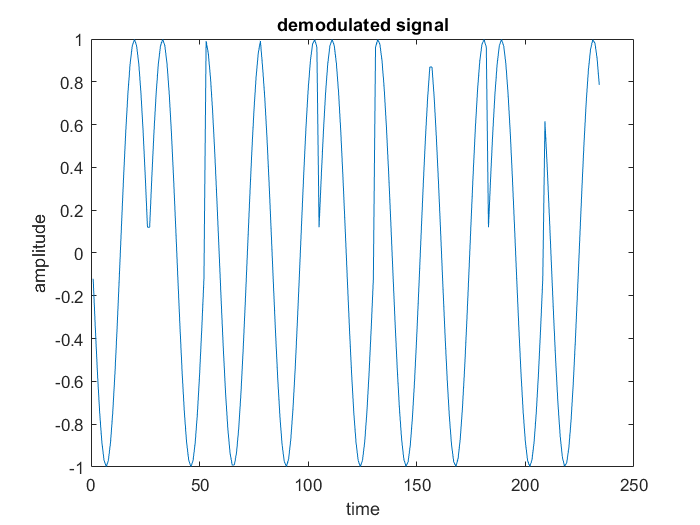

% demodulation
rt = modulated;
Ns = round(fs / fc);
demodulated = zeros([1, floor(length(rt) * fc/fs)]);
dcounter = 1;
for n = Ns:Ns:length(rt)
    r_hat_t = rt(n-Ns+1:n) .* sin(2*pi*fc*(0:Ns-1)*Ts);
    demodulated(dcounter) = sum(r_hat_t)*Ts*2/Tc;
    dcounter = dcounter + 1;
end
figure()
plot(demodulated); xlabel('time'); ylabel('amplitude'); title('demodulated signal');

Decoding tries to find the indices of transmitted symbols.

Detection means finding the message that has been transmitted.

There are several methods to decode the received signal, but the correlation decoder is the most common. The matched filter is an LTI implementation of correlator, so both are the same with different formulation.

If the received signal is $r\left(t\right)$ and the base encoding signal is $s\left(t\right)$ then correlator decoder works as follow:


$$a=\int_0^{T_b } r\left(t\right)s\left(t\right)\textrm{dt}$$


The detection will be done with coefficient $a$, for example with a threshold.

If we have several orthonormal encoding signal ($s_i \left(t\right)$) then several coefficients will be computed as follow:


$$a_i =\int_0^{T_b } r\left(t\right)s_i \left(t\right)\textrm{dt}$$


Then detection will be done with all coefficiens $\left\lbrace a_1 ,a_2 ,\;\ldotp \ldotp \ldotp ,a_m \right\rbrace$

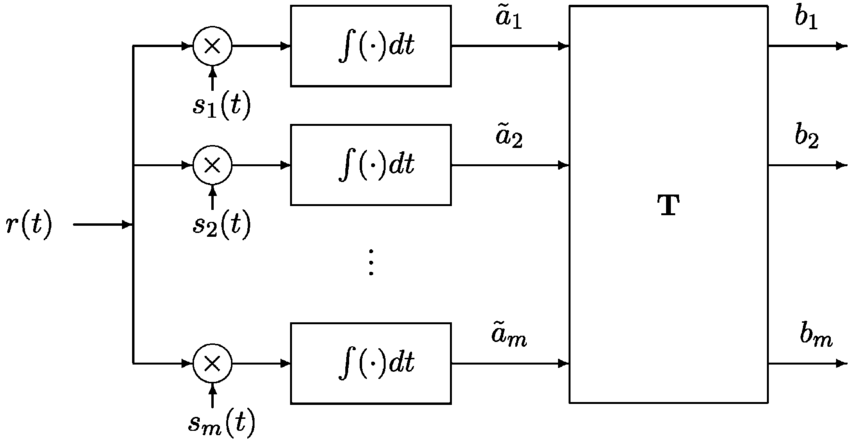

### Section 05

#### PSK Correlator Decoder and Detection

Since sinusoids with different phases have been used for encoding, there are two orthogonal functions and two correlators are needed for detection.


$$a_1 =\int_0^{T_b } r\left(t\right)\cos \left(2\pi r_b t\right)\textrm{dt}$$



$$a_2 =\int_0^{T_b } r\left(t\right)\sin \left(2\pi r_b t\right)\textrm{dt}$$


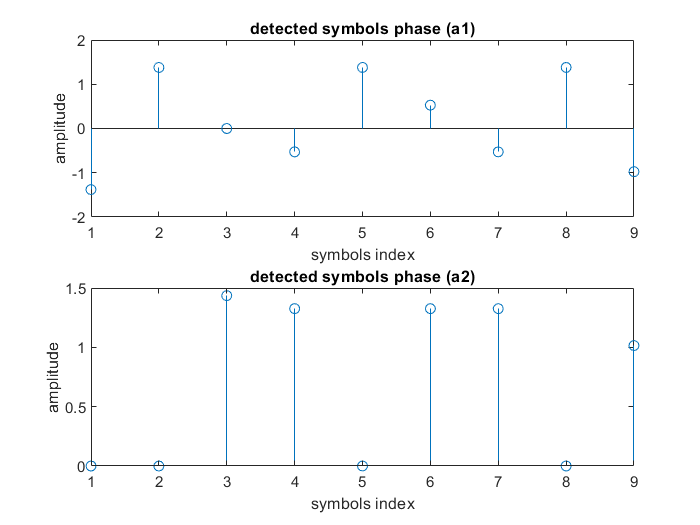

% decoding
rt = demodulated;
Ns = round(fc / rb);
a1 = zeros([1, floor(length(rt) * rb / fc)]);
a2 = zeros([1, floor(length(rt) * rb / fc)]);
dcounter = 1;
for n = Ns:Ns:length(rt)
    % computing a1 (quadrature)
    r_hat_t = rt(n-Ns+1:n) .* sin(2*pi* (fc/rb) * (0:Ns-1)/(Ns-1) * Tc/Tb);
    a1(dcounter) = sum(r_hat_t)*(Tc/Tb)*sqrt(2)*2;
    % computing a2 (in-phase)
    % r_hat_t = rt(n-Ns+1:n) .* sin(2*pi* (fc/rb) * (0:Ns-1)/(Ns-1) * Tc/Tb + pi/2);
    r_hat_t = rt(n-Ns+1:n) .* cos(2*pi* (fc/rb) * (0:Ns-1)/(Ns-1) * Tc/Tb);
    a2(dcounter) = sum(r_hat_t)*(Tc/Tb)*sqrt(2)*2;
    dcounter = dcounter + 1;
end
figure()
subplot(2, 1, 1); stem(a1); xlabel('symbols index'); ylabel('amplitude'); title('detected symbols phase (a1)');
subplot(2, 1, 2); stem(a2); xlabel('symbols index'); ylabel('amplitude'); title('detected symbols phase (a2)');

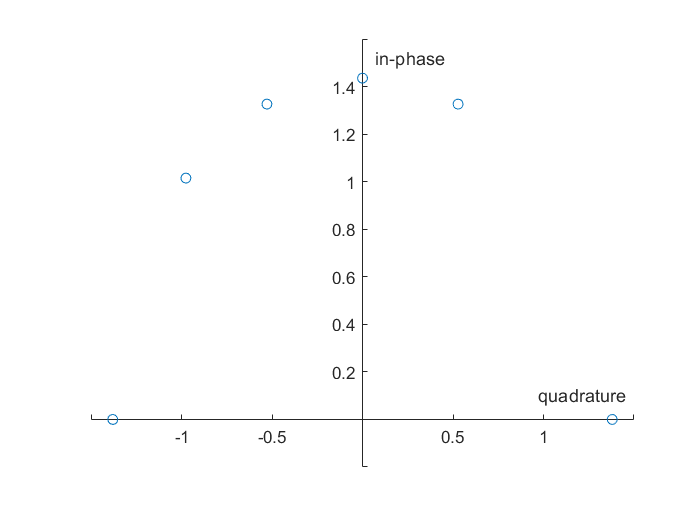

figure(); scatter(a1, a2);
set(gca, 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');
xlabel('quadrature'); ylabel('in-phase');

% detection
%centers_complex = (a1 + 1j * a2) ./ sqrt(a1.^2 + a2.^2)
centers_complex=[1.00000000000000 - 6.49966021217594e-16i	0.918350806648619 + 0.395767350760306i	0.692964664150091 + 0.720971548841805i	0.369886854028270 + 0.929076808028846i	2.97899319764270e-15 + 1.00000000000000i	-0.369886854028265 + 0.929076808028848i	-0.692964664150086 + 0.720971548841810i	-0.918350806648616 + 0.395767350760314i	-1.00000000000000 + 5.80811387310267e-15i	-0.918350806648621 - 0.395767350760302i	-0.692964664150094 - 0.720971548841802i	-0.369886854028275 - 0.929076808028844i	-9.39444144612504e-15 - 1.00000000000000i	0.369886854028257 - 0.929076808028851i	0.692964664150080 - 0.720971548841816i	0.918350806648612 - 0.395767350760321i]

centers_complex =    1.0000 - 0.0000i   0.9184 + 0.3958i   0.6930 + 0.7210i   0.3699 + 0.9291i   0.0000 + 1.0000i  -0.3699 + 0.9291i  -0.6930 + 0.7210i  -0.9184 + 0.3958i  -1.0000 + 0.0000i  -0.9184 - 0.3958i  -0.6930 - 0.7210i  -0.3699 - 0.9291i  -0.0000 - 1.0000i   0.3699 - 0.9291i   0.6930 - 0.7210i   0.9184 - 0.3958i


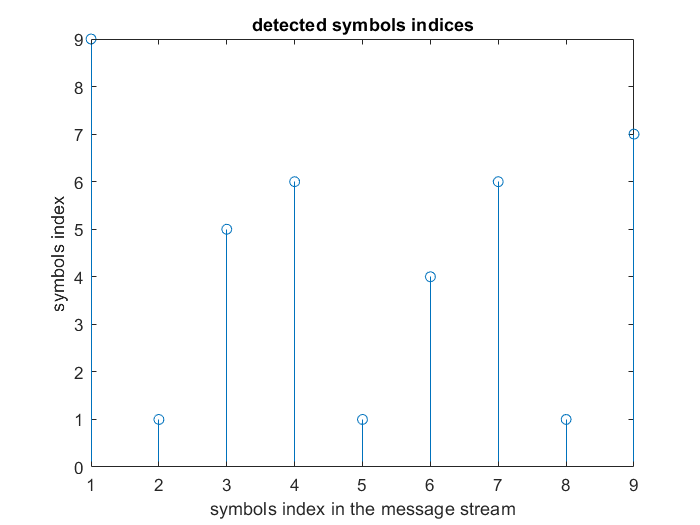

decoding_table = 1:M;
detected_indices = zeros([1, length(a1)]);
for n = 1:length(a1)
    distances = abs(centers_complex - (a1(n) + 1j * a2(n))./sqrt(a1(n).^2 + a2(n).^2));
    detected_indices(n) = decoding_table(distances == min(min(distances)));
end
figure()
stem(detected_indices); xlabel('symbols index in the message stream'); ylabel('symbols index'); title('detected symbols indices');

% computing error rates
err = mean(msg ~= detected_indices)

err = 0

### Section 06

#### Noise

Noise is the impact of channel that signal transfer through.

The most common way to find the noise impact is Additive White Gaussian Noise (AWGN) model. In this model, the noise will be generted by a Gaussian distribution and added to the transmitted signal.

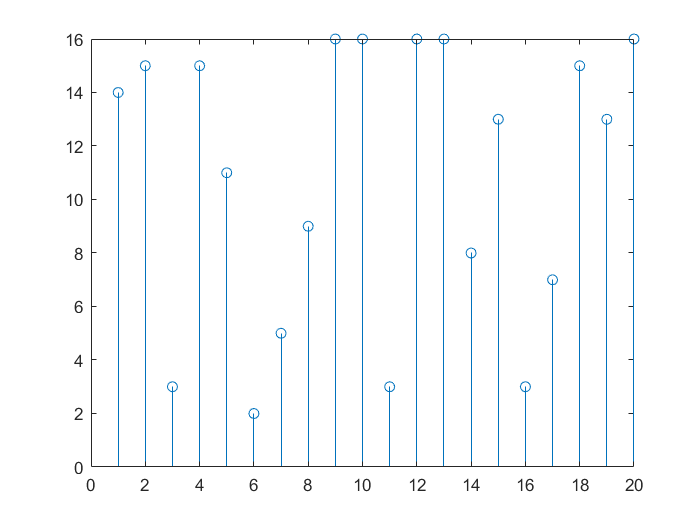

% generation of a random message with fixed length
rng(0);
Nm = 1000;
msg = randi(M, [1, Nm]);                            % message: a set of symbols
figure(); stem(msg(1:20));

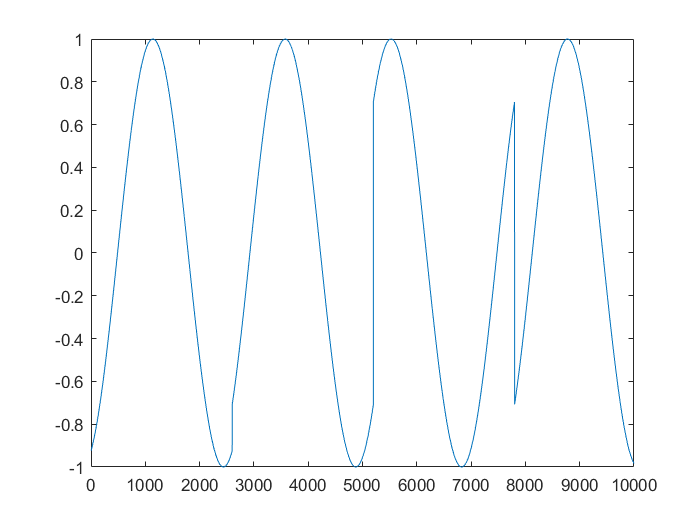

msg_phase = symbol_phase(symbol_set(msg));  % mepping the symbol to the amplitude
phases = rate_transition(msg_phase, rb, fs); % translate rate 1 to rate rb
t = (0:length(phases)-1)*Ts;                    % make the parameter time
signal = A * sin(2 * pi * rb * t + phases);     % baseband signal
figure(); plot(signal(1:10000));

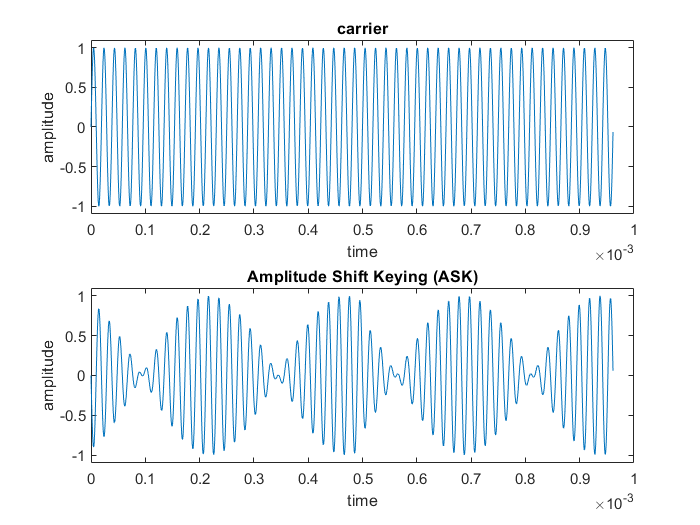

carrier = 1 * sin(2 * pi * fc * t + 0);
modulated = signal .* carrier;
figure()
subplot(2, 1, 1); plot(t(1:5000), carrier(1:5000)); xlabel('time'); ylabel('amplitude'); ylim([-A-0.1, +A+0.1]); title('carrier');
subplot(2, 1, 2); plot(t(1:5000), modulated(1:5000)); xlabel('time'); ylabel('amplitude'); ylim([-A-0.1, +A+0.1]); title('Amplitude Shift Keying (ASK)');

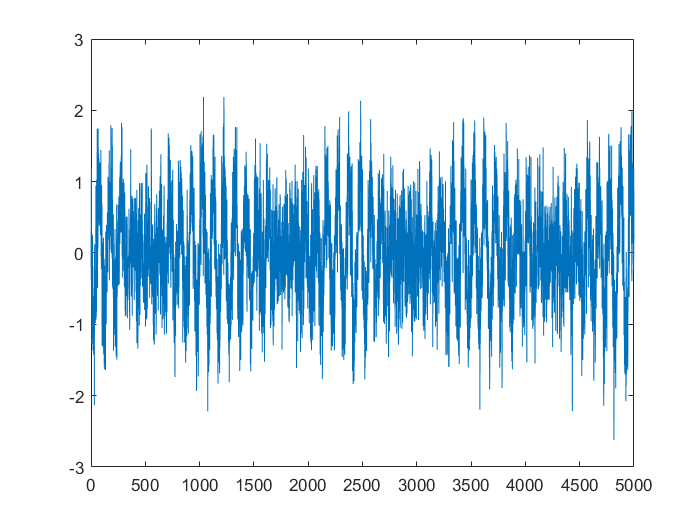

snr = 0;
noisy_signal = awgn(modulated, snr, 'measured');
figure(); plot(noisy_signal(1:5000));

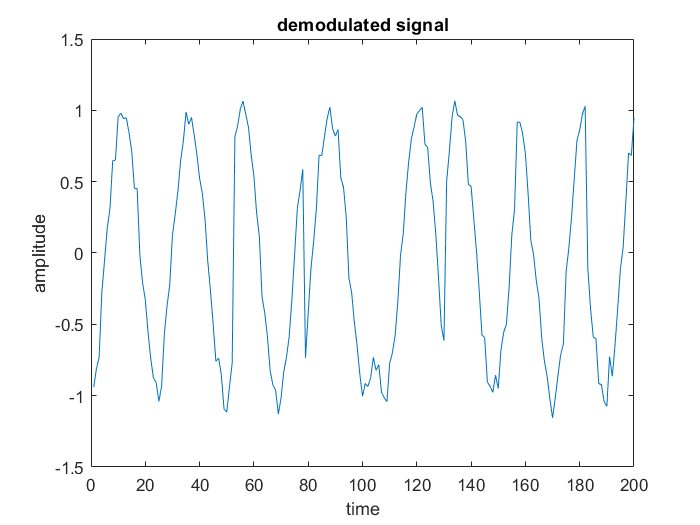

% demodulation
rt = noisy_signal;
Ns = round(fs / fc);
demodulated = zeros([1, floor(length(rt) * fc/fs)]);
dcounter = 1;
for n = Ns:Ns:length(rt)
    r_hat_t = rt(n-Ns+1:n) .* sin(2*pi*fc*(0:Ns-1)*Ts);
    demodulated(dcounter) = sum(r_hat_t)*Ts*2/Tc;
    dcounter = dcounter + 1;
end
figure()
plot(demodulated(1:200)); xlabel('time'); ylabel('amplitude'); title('demodulated signal');

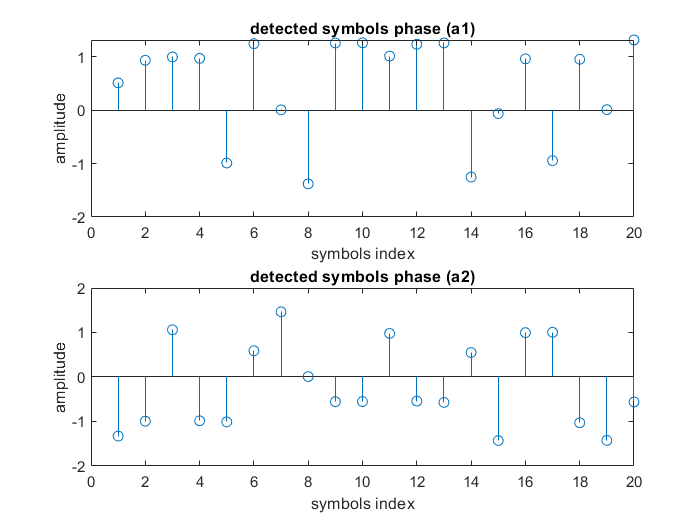

% decoding
rt = demodulated;
Ns = round(fc / rb);
a1 = zeros([1, floor(length(rt) * rb / fc)]);
a2 = zeros([1, floor(length(rt) * rb / fc)]);
dcounter = 1;
for n = Ns:Ns:length(rt)
    % computing a1 (quadrature)
    r_hat_t = rt(n-Ns+1:n) .* sin(2*pi* (fc/rb) * (0:Ns-1)/(Ns-1) * Tc/Tb);
    a1(dcounter) = sum(r_hat_t)*(Tc/Tb)*sqrt(2)*2;
    % computing a2 (in-phase)
    % r_hat_t = rt(n-Ns+1:n) .* sin(2*pi* (fc/rb) * (0:Ns-1)/(Ns-1) * Tc/Tb + pi/2);
    r_hat_t = rt(n-Ns+1:n) .* cos(2*pi* (fc/rb) * (0:Ns-1)/(Ns-1) * Tc/Tb);
    a2(dcounter) = sum(r_hat_t)*(Tc/Tb)*sqrt(2)*2;
    dcounter = dcounter + 1;
end
figure()
subplot(2, 1, 1); stem(a1(1:20)); xlabel('symbols index'); ylabel('amplitude'); title('detected symbols phase (a1)');
subplot(2, 1, 2); stem(a2(1:20)); xlabel('symbols index'); ylabel('amplitude'); title('detected symbols phase (a2)');

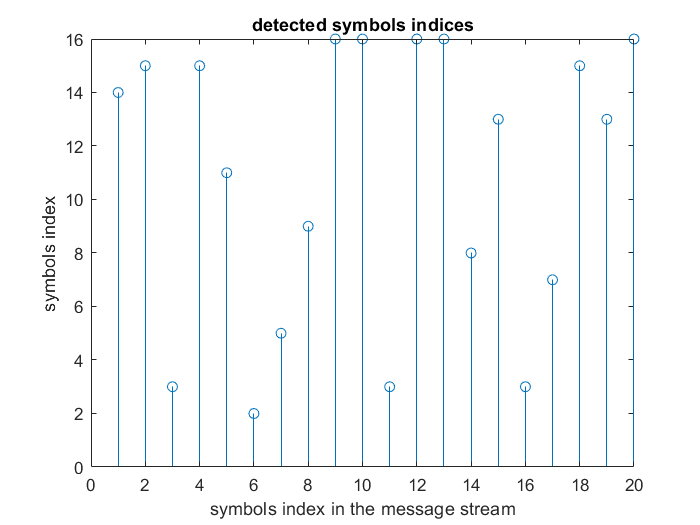

detected_indices = zeros([1, length(a1)]);
for n = 1:length(a1)
    distances = abs(centers_complex - (a1(n) + 1j * a2(n))./sqrt(a1(n).^2 + a2(n).^2));
    detected_indices(n) = decoding_table(distances == min(min(distances)));
end
figure()
stem(detected_indices(1:20)); xlabel('symbols index in the message stream'); ylabel('symbols index'); title('detected symbols indices');

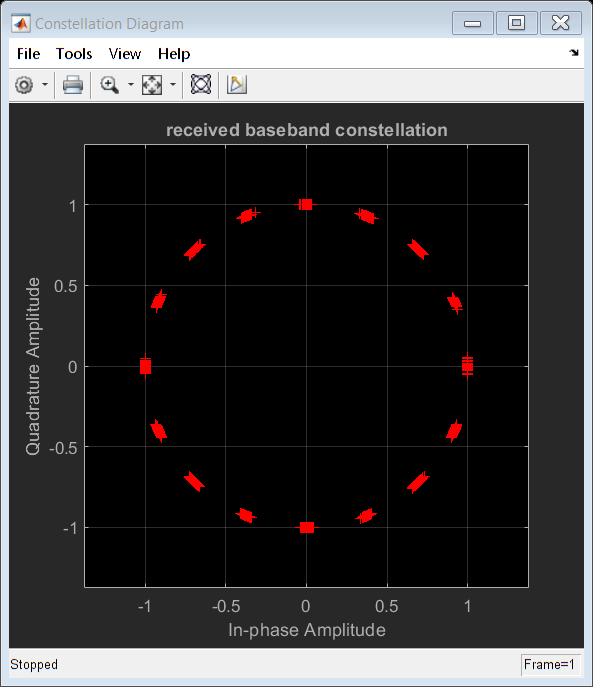

decoded_complex = (a1 + 1j * a2)./sqrt(a1.^2 + a2.^2);
constdiag = comm.ConstellationDiagram;
constdiag.Title = "received baseband constellation";
% constdiag.SymbolsToDisplay = 10000;
constdiag.ShowLegend = false;
constdiag.ReferenceConstellation = decoded_complex';
constdiag(symbol_set_complex');
constdiag.release();    

% computing error rates
err = mean(msg ~= detected_indices)

err = 0

### Section 07

Power spectrum of the **baseband** signal:

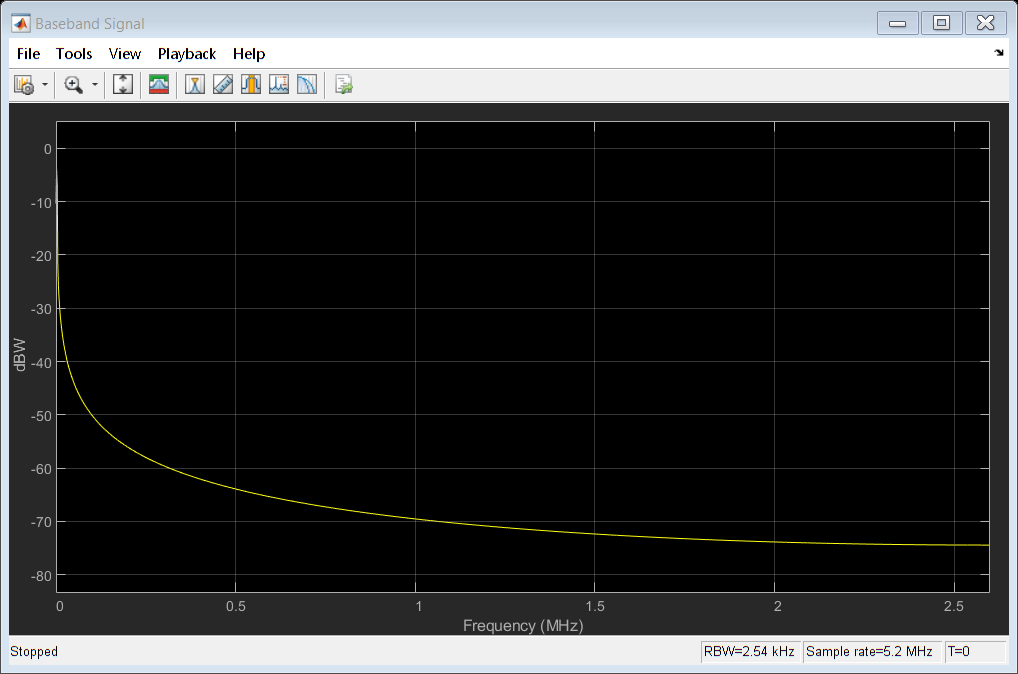

scope1 = dsp.SpectrumAnalyzer();
scope1.SampleRate = fs;
scope1.PlotAsTwoSidedSpectrum = false;
scope1.SpectrumUnits = "dBW";
scope1(signal');
scope1.Name = 'Baseband Signal';
release(scope1);

Power spectrum of the **carrier** signal:

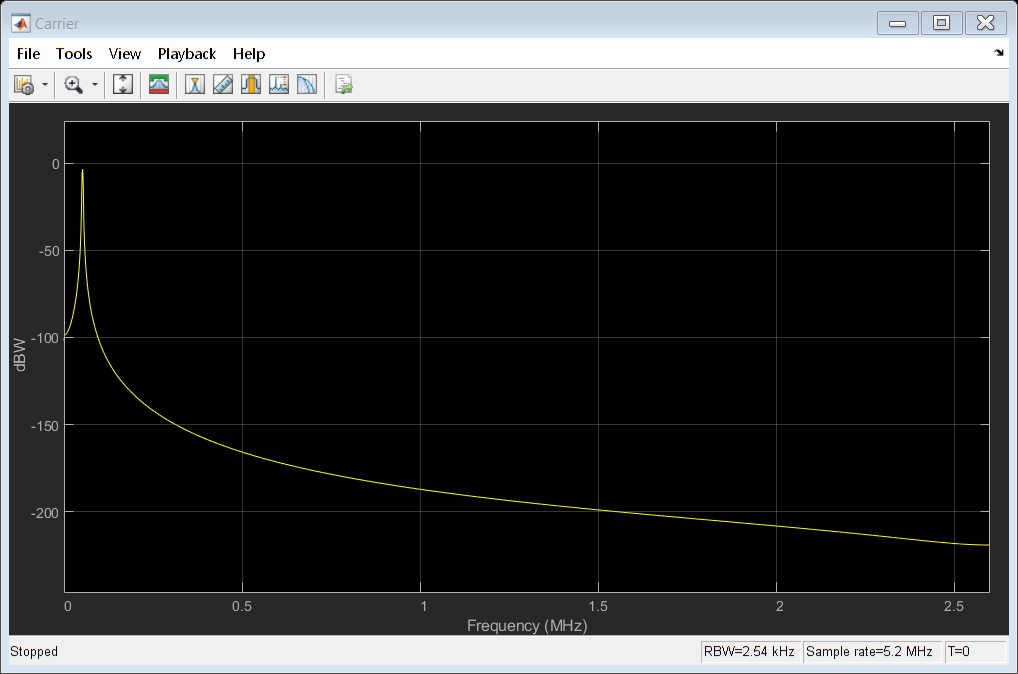

scope2 = dsp.SpectrumAnalyzer();
scope2.SampleRate = fs;
scope2.PlotAsTwoSidedSpectrum = false;
scope2.SpectrumUnits = "dBW";
scope2(carrier');
scope2.Name = 'Carrier';
release(scope2);

Power spectrum of the **modulated (passband)** signal:

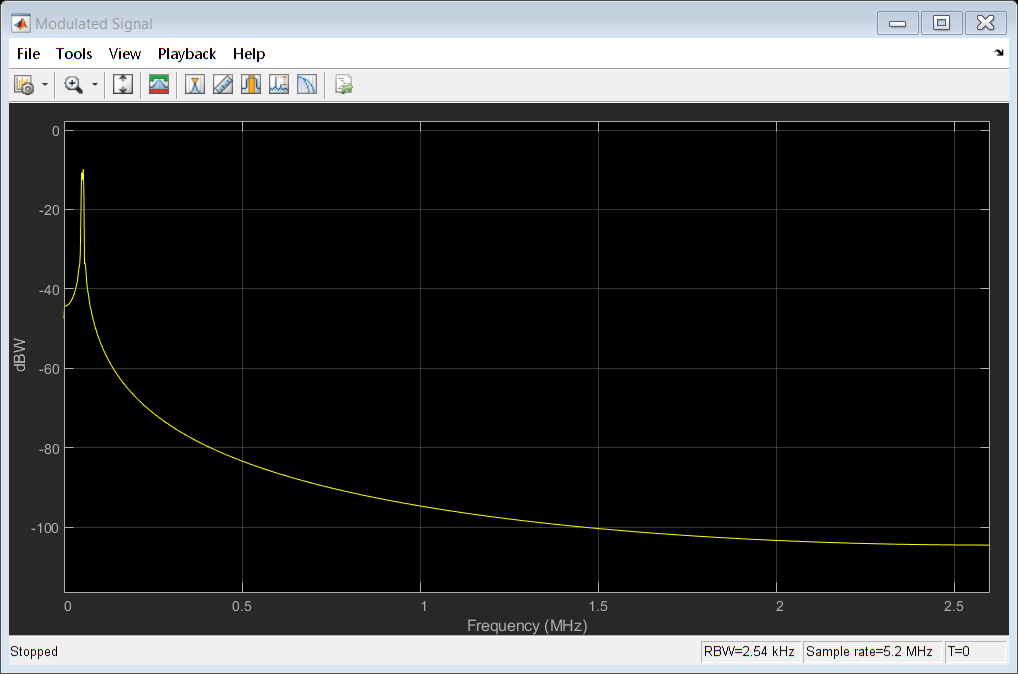

scope3 = dsp.SpectrumAnalyzer();
scope3.SampleRate = fs;
scope3.PlotAsTwoSidedSpectrum = false;
scope3.SpectrumUnits = "dBW";
scope3(modulated');
scope3.Name = 'Modulated Signal';
release(scope3);

Power spectrum of the **recieved** signal:

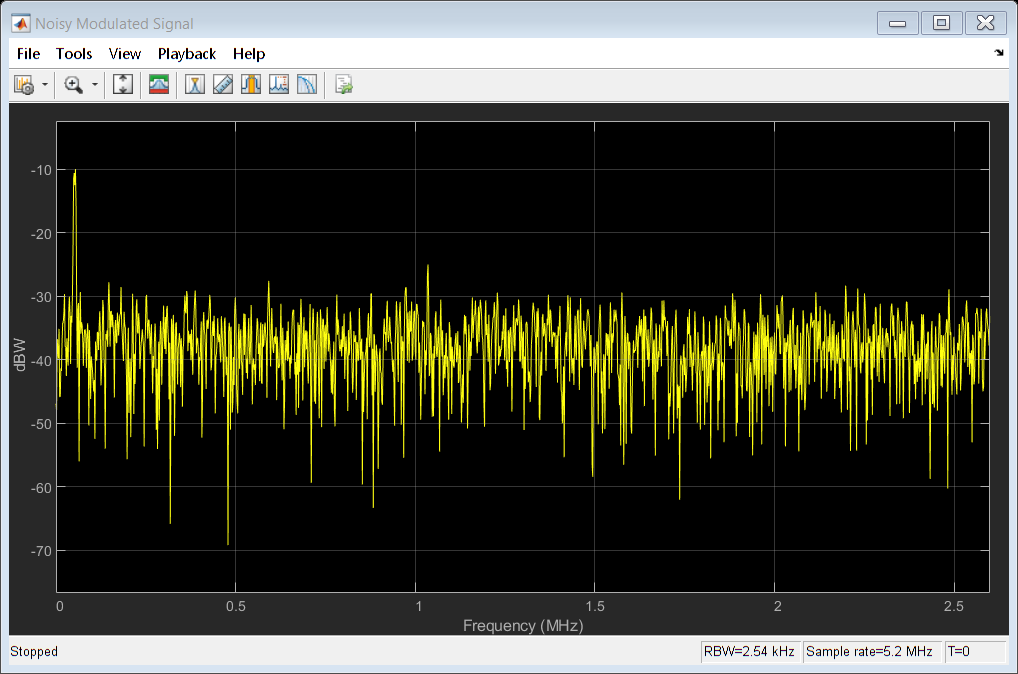

scope4 = dsp.SpectrumAnalyzer();
scope4.SampleRate = fs;
scope4.PlotAsTwoSidedSpectrum = false;
scope4.SpectrumUnits = "dBW";
scope4(noisy_signal');
scope4.Name = 'Noisy Modulated Signal';
release(scope4);

### Functions Definition

Rate transition:

function rt = rate_transition(s, f1, f2)
    if (f1 < f2)
        rt = repelem(s, floor(f2/f1));
        % x = 0:1/f1:((length(s)-1)*1/f1);
        % xq = 0:1/f2:((length(s)-1)*1/f1);
        % rt = interp1(x, s, xq, 'linear');
    else
        step = floor(f1/f2);
        rt = s(1:step:end);
    end
end